Improving PAM cryptic species figure:

- 2 minute (or subsampled spectrograms)

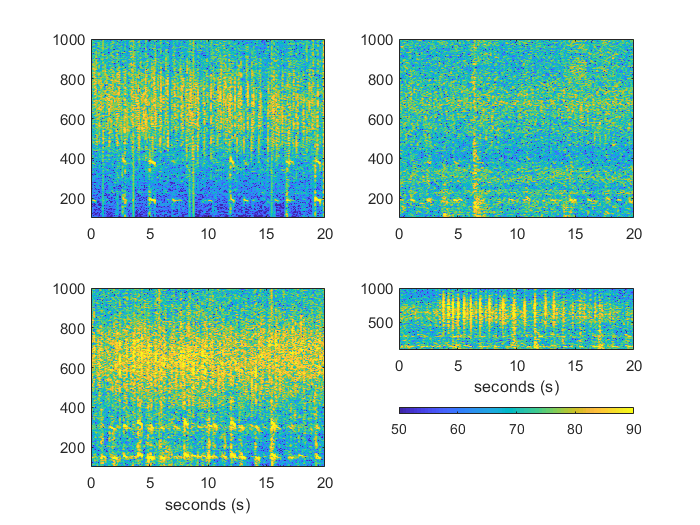

% load file
% calculate FFT and save variables
%plot

clear
% I1
highgain=169; cal=10^(highgain/20);
[y,fs]=audioread('D:\Succession_Subsample\Indra_D1\1074278447.160518003000.wav');
y=(y-mean(y))*cal;
freqlim=[100,10000];
yfilt=bandpass_del(y,freqlim(1),freqlim(2),fs,3); 
yfilt_I1=yfilt(21*fs:41*fs); % subset to rel time within file in samples
NFFT=2^15; 
[~,F_I1,T_I1,Pxx_I1]=spectrogram(yfilt_I1,NFFT,floor(0.9*NFFT),[],fs); %0.05sec windows, 50% overlap
t_I1=(0:1:length(yfilt_I1)-1)*(1/fs); % make time vector to match subset

%J1 
% consider picking a better section that has more toadfish 
highgain=169; cal=10^(highgain/20);
[y,fs]=audioread('D:\Succession_Subsample\1074012205.160518004500.wav');
y=(y-mean(y))*cal;
%freqlim=[150,10000];
yfilt=bandpass_del(y,freqlim(1),freqlim(2),fs,3); 
%yfilt_J1 = yfilt;
yfilt_J1=yfilt(85*fs:105*fs); % subset to rel time within file in samples
NFFT=2^15; 
[~,F_J1,T_J1,Pxx_J1]=spectrogram(yfilt_J1,NFFT,floor(0.9*NFFT),[],fs); %0.05sec windows, 50% overlap
t_J1=(0:1:length(yfilt_J1)-1)*(1/fs); % make time vector to match subset

%I6
highgain=169; cal=10^(highgain/20);
[y,fs]=audioread('D:\Succession_Subsample\Indra_D6\1074012205.170422004500.wav');
y=(y-mean(y))*cal;
%freqlim=[150,10000];
yfilt=bandpass_del(y,freqlim(1),freqlim(2),fs,3);
%yfilt_I6 = yfilt;
yfilt_I6=yfilt(1*fs:21*fs); % subset to rel time within file in samples
NFFT=2^15; 
[~,F_I6,T_I6,Pxx_I6]=spectrogram(yfilt_I6,NFFT,floor(0.9*NFFT),[],fs); %0.05sec windows, 50% overlap
t_I6=(0:1:length(yfilt_I6)-1)*(1/fs); % make time vector to match subset

%J6
highgain=169; cal=10^(highgain/20);
[y,fs]=audioread('D:\Succession_Subsample\JJTug_D6\1074028589.170422004500.wav');
y=(y-mean(y))*cal;
%freqlim=[150,10000];
yfilt=bandpass_del(y,freqlim(1),freqlim(2),fs,3);
%yfilt_J6 = yfilt;
yfilt_J6=yfilt(1*fs:21*fs); % subset to rel time within file in samples
NFFT=2^15; 
[~,F_J6,T_J6,Pxx_J6]=spectrogram(yfilt_J6,NFFT,floor(0.9*NFFT),[],fs); %0.05sec windows, 50% overlap
t_J6=(0:1:length(yfilt_J6)-1)*(1/fs); % make time vector to match subset

%band = find(F_I1 >=100 & F_I1 <=1000);

% Plotting
figure; %set(gcf,'units','centimeters','position',[0,0,11.3,18]);
subplot(2,2,1); imagesc(t_I1,F_I1,10*log10(Pxx_I1));
%pcolor(t_I1,band,log10(Pxx_I1(band,:)))
caxis([50,90]); %caxis([45,90]);
%colorbar('eastoutside');
ylim([100 1000]);axis xy; %yticks([100 500 1000]); 
%xticks([0 1 2 3 4]); xticklabels([0 1 2 3 4]);

subplot(2,2,2); imagesc(t_J1,F_J1,10*log10(Pxx_J1));
caxis([50,90]); %caxis([45,90]);
%colorbar('eastoutside');
ylim([100 1000]);axis xy; %yticks([100 500 1000]); 
%xticks([0 1 2 3 4]); xticklabels([0 1 2 3 4]);

subplot(2,2,3); imagesc(t_I6,F_I6,10*log10(Pxx_I6));
caxis([50,90]); %caxis([45,90]);
%colorbar('eastoutside');
ylim([100 1000]);axis xy; %yticks([100 500 1000]); 
%xticks([0 1 2 3 4]); xticklabels([0 1 2 3 4]);
xlabel('seconds (s)');

subplot(2,2,4); imagesc(t_J6,F_J6,10*log10(Pxx_J6));
caxis([50,90]); %caxis([45,90]);
xlabel('seconds (s)');
colorbar('southoutside');
ylim([100 1000]);axis xy; %yticks([100 500 1000]); 

%xticks([0 1 2 3 4]); xticklabels([0 1 2 3 4]);


        2. 2 minute power spectra -  